## HW2

**本次作业截止时间为3月22日（周五）晚，请同时提交mlx和pdf版本文件**

1. 【流程控制】采用阶梯法测量某感觉阈限，刺激强度根据被试的判断一间隔相等的小步变化，探索被试从一种反应转换到另一种反应的阈限位置。被试若能够感受到刺激，判断为“有”，则下次刺激强度减弱，否则下次刺激强度提高。初始刺激强度A0=100，变化量m=2.5。每个试次中，如果刺激强度为A，被试根据随机信号 P = 30 + randi(5)进行反应，A≥P 反应为“有”，否则记为“无”。当被试的判断和上次不一样时，当前刺激强度被视为一个转折点。经过8个转折点或200次试验后结束。请模拟这一过程，记录每次的刺激大小和随机信号，并计算感觉阈限的测量值（感觉阈限按照转折点的算术平均值计算）。

A = 100;
vari = 2.5;
count = 0;
time = 1;
result = 0;
while count < 8 & time <= 200
    P = 30 + randi(5);
    judge = A >= P;
    if time ~= 1
        count = count + (judge ~= lastjudge);
        result = result + A*(judge ~= lastjudge);
        lastjudge = judge;
        A = A + vari*(0.5-judge)*2;
    else
        lastjudge = judge;
    end
    time = time + 1;
end
disp(result / count)

   32.8125



2. 【RGB图片色彩空间在三维矩阵上的表示】

2.1 绘制视觉马赫带图案（如下图），大小为200*200，共有10条亮度带，从左向右亮度线性递增

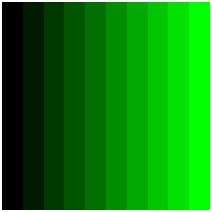

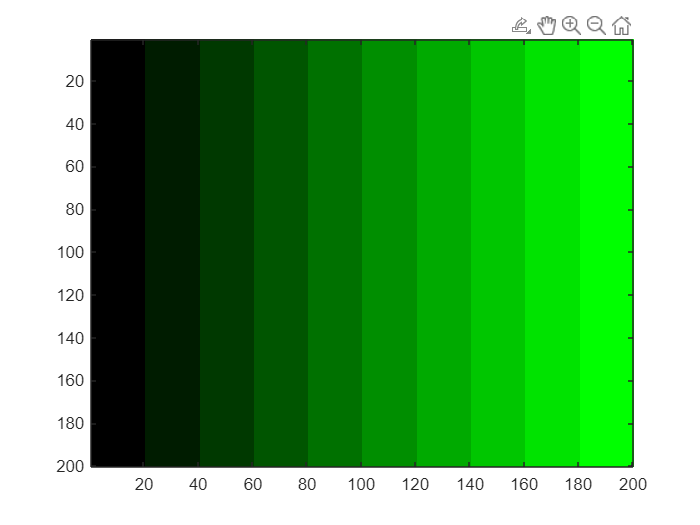

block = uint8(zeros(200,200,3));
light = linspace(0,255,10);
for i = 1:10
    block(:,(20*(i-1)+1):(20*i),2) = light(i);
end
image(block)

2.2 封装一个函数，画出类似上面的马赫带图，大小仍然为200*200，但可以（1）选择条纹个数（2）选择红绿蓝三种颜色

提示：使用function


% function Machband(num_line, R, G, B)
% block = uint8(zeros(200,200,3));
% lightR = linspace(0, R, num_line);
% lightG = linspace(0, G, num_line);
% lightB = linspace(0, B, num_line);
% for i = 1:10
%     block(:,(20*(i-1)+(i==1)+1):(20*i),1) = lightR(i);
%     block(:,(20*(i-1)+(i==1)+1):(20*i),2) = lightG(i);
%     block(:,(20*(i-1)+(i==1)+1):(20*i),3) = lightB(i);
% end
% image(block)
% end


3. 

3.1 绘制图像如下图所示，大小为1000*1000，底色为灰色（灰度任意），并以中心为圆心、250为半径画一个黑色的圆

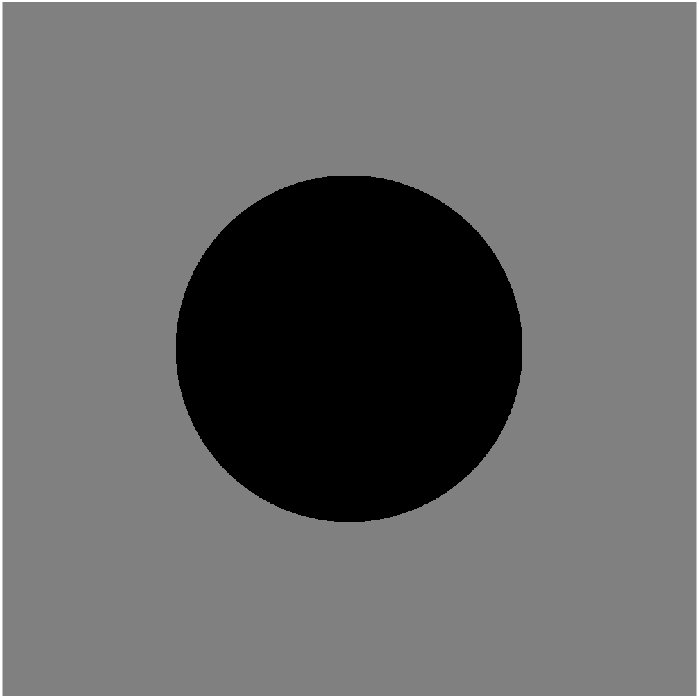

提示：可以尝试多种画法（比如使用meshgrid()）

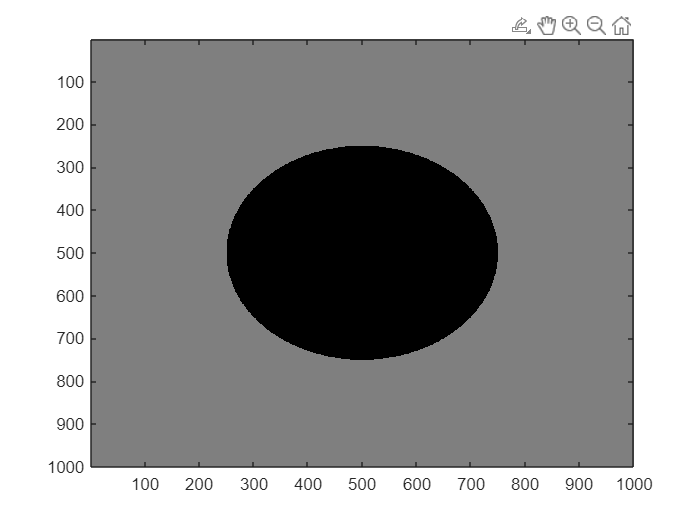

width = 1000;
height = 1000;
block2 = uint8(zeros(width,height,3));
centerX = width / 2;
centerY = height / 2;
for x = 1:1000
    for y = 1:1000
        if (x-centerX)^2 + (y-centerY)^2 > 250^2
            block2(x, y, :) = 127;
        end
    end
end
image(block2)

3.2 绘制图像如下图所示：相邻圆心间等距，共5*5=25个，底色黑色，圆的灰度任意，图像大小不作要求

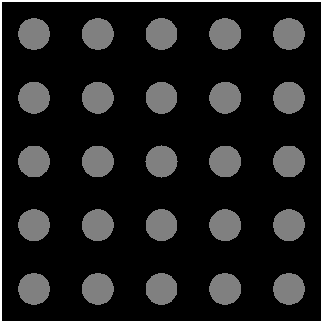

提示：使用循环

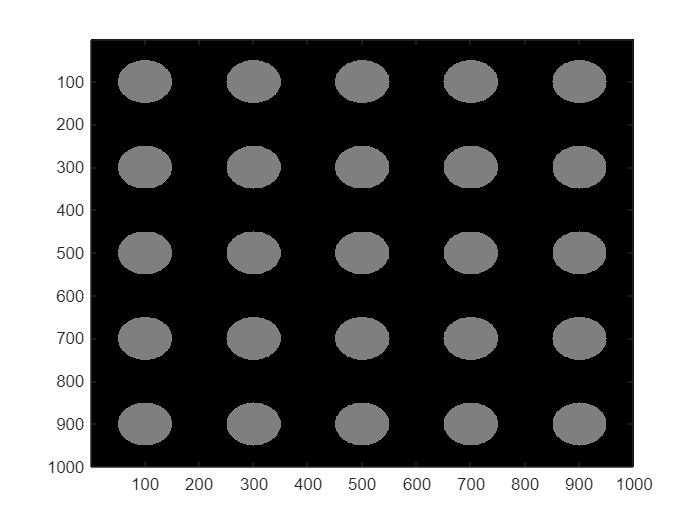

block3 = uint8(zeros(200,200,3));
centerX = 100;
centerY = 100;
for x = 1:200
    for y = 1:200
        if (x-centerX)^2 + (y-centerY)^2 <= 50^2
            block3(x, y, :) = 127;
        end
    end
end
block3 = repmat(block3, 5);
image(block3)